clc; clear; close all;

C = 27;
d = 4;
n_r = 6;

%% Loading FC Data
if(exist(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']) == 0 | ...
   exist(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']) == 0)
    disp('FC data not found. Generating FC operators... \n');
    generate_bdry_continuations(d, C, C, 12, 20, 4, ...
        256, n_r);
end

load(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']);

A = double(A);
Q = double(Q);

n_bound = 640;
R_h = 0.2/(n_bound)

R_h = 3.1250e-04


f = @(x, y) f_func(x, y);
C1_patch = construct_C1_patch(f, 0.2, 2*pi-0.2, 0, -0.2, 2*pi+0.2, n_bound);

[C1_fcont_patch_xi, C1_fcont_patch_eta_refined, C1_fcont_patch_eta_unrefined, B_fcont, B_c_minus_fcont] = C1_patch.FC(C, n_r, d, A, Q, f);

R_x_bounds = [-0.45, 0.55]

R_x_bounds =    -0.4500    0.5500


R_y_bounds = [-0.45, 0.45]

R_y_bounds =    -0.4500    0.4500



[boundary_X, boundary_Y] = C1_patch.boundary_mesh_xy;

R = R_cartesian_mesh_obj(R_x_bounds(1), R_x_bounds(2), R_y_bounds(1), R_y_bounds(2), R_h, boundary_X, boundary_Y);
% hold on;
% scatter(R.R_X(:), R.R_Y(:));
R.interpolate_patch(C1_fcont_patch_xi, d+3, false, f);

start first pass
construct nan map



R.interpolate_patch(C1_fcont_patch_eta_refined, d+3, false, f);

start first pass
construct nan map


R.interpolate_patch(C1_fcont_patch_eta_unrefined, d+3, false, f);

start first pass
construct nan map


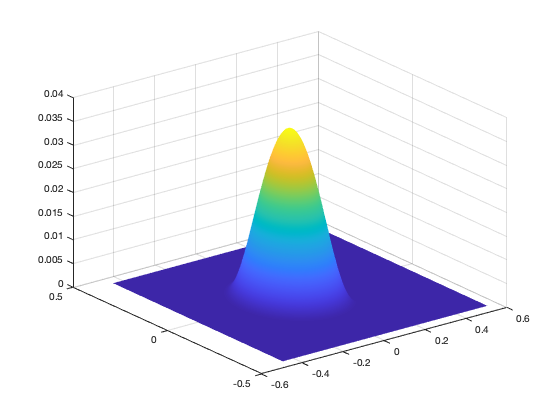


R.fill_interior(f);

figure;
s = surf(R.R_X, R.R_Y, R.f_R);
s.EdgeColor = 'none';


R.compute_fc_coeffs()
[X_err, Y_err, f_err, err_interior_idx] = R.ifft_interpolation(R.h * 0.5);

max(abs((f(X_err(err_interior_idx), Y_err(err_interior_idx)) - f_err(err_interior_idx)))) %l_infinity error

ans = 2.8762e-13

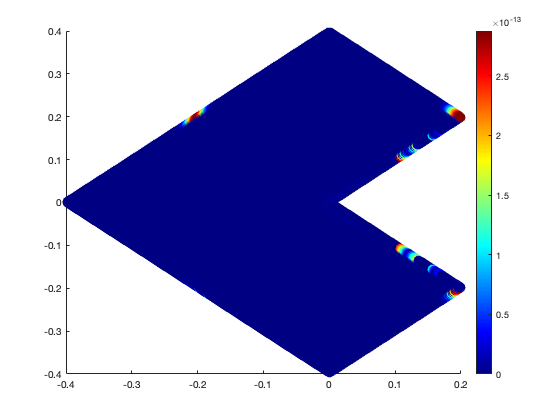


err = abs((f(X_err(err_interior_idx), Y_err(err_interior_idx)) - f_err(err_interior_idx)));

figure;
scatter(X_err(err_interior_idx), Y_err(err_interior_idx), 100, err, 'filled');

% Add a color bar
colorbar;

% Set colormap
colormap(jet);

xi_mesh = C1_patch.B.eta_mesh;
eta_mesh = xi_mesh;
R_mesh = zeros(length(eta_mesh), length(xi_mesh));

R_mesh(:, n_bound+1-C:n_bound+1) = B_fcont(:, 1:n_r:C*n_r+1);
R_mesh(:, n_bound+1:end) = C1_patch.B.f_XY(:, 1:end);

C1_fcont_patch_FFT_xi = construct_Q_patch(R_mesh, 0.2, 2*pi-0.2, 0, -0.2, 2*pi+0.2, n_bound);
C1_fcont_patch_FFT_xi.compute_xi_eta_fc_coeffs;

R_mesh = zeros(length(eta_mesh), length(xi_mesh));

R_mesh(n_bound+1:end, 1:n_bound+1) = B_c_minus_fcont;
R_mesh(n_bound+1-C:n_bound+1, 1:n_bound+1) = C1_fcont_patch_eta.f_XY(1:n_r:C*n_r+1, :);

C1_fcont_patch_FFT_eta = construct_Q_patch(R_mesh, 0.2, 2*pi-0.2, 0, -0.2, 2*pi+0.2, n_bound);
C1_fcont_patch_FFT_eta.compute_xi_eta_fc_coeffs;

R_mesh = zeros(length(eta_mesh), length(xi_mesh));

R_mesh(1:n_bound+1, n_bound+1-C:n_bound+1) = C1_fcont_patch_xi.f_XY(:, 1:n_r:end);
R_mesh(n_bound+1-C:n_bound+1, 1:n_bound+1) = R_mesh(n_bound+1-C:n_bound+1, 1:n_bound+1) + C1_fcont_patch_eta.f_XY(1:n_r:end, :);
R_mesh(n_bound+2:end, 1:n_bound+1) = C1_patch.B_c.f_XY(2:end, :);
R_mesh(:, n_bound+2:end) = C1_patch.B.f_XY(:, 2:end);

C1_fcont_patch_FFT = construct_Q_patch(R_mesh, 0.2, 2*pi-0.2, 0, -0.2, 2*pi+0.2, n_bound);
C1_fcont_patch_FFT.compute_xi_eta_fc_coeffs;

local_compute_xi = zeros(size(C1_fcont_patch_xi.f_XY));
local_compute_eta = zeros(size(C1_fcont_patch_eta.f_XY));

[XI_xi, ETA_xi] = C1_fcont_patch_xi.xi_eta_mesh;

for i = 1:size(local_compute_xi, 1)
    for j = 1:size(local_compute_xi, 2)
        local_compute_xi(i, j) = C1_fcont_patch_FFT_xi.locally_compute_FFT(XI_xi(i, j), ETA_xi(i, j));
    end
end

[XI_eta, ETA_eta] = C1_fcont_patch_eta.xi_eta_mesh;

for i = 1:size(local_compute_eta, 1)
    for j = 1:size(local_compute_eta, 2)
        local_compute_eta(i, j) = C1_fcont_patch_FFT_eta.locally_compute_FFT(XI_eta(i, j), ETA_eta(i, j));
    end
end

max(abs(local_compute_xi - C1_fcont_patch_xi.f_XY), [], 'all')
max(abs(local_compute_eta - C1_fcont_patch_eta.f_XY), [], 'all')

figure;
s = surf(XI_eta, ETA_eta, C1_fcont_patch_eta.f_XY);
s.EdgeColor = 'none';

%% do test in xy space

R_x_bounds = [-0.45, 0.55];
R_y_bounds = [-0.45, 0.45];

[boundary_X, boundary_Y] = C1_patch.boundary_mesh_xy;

R_poly = R_cartesian_mesh_obj(R_x_bounds(1), R_x_bounds(2), R_y_bounds(1), R_y_bounds(2), R_h, boundary_X, boundary_Y);
R_FFT = R_cartesian_mesh_obj(R_x_bounds(1), R_x_bounds(2), R_y_bounds(1), R_y_bounds(2), R_h, boundary_X, boundary_Y);

R_poly.interpolate_patch(C1_fcont_patch_xi, d+3, false, f);
R_FFT.interpolate_patch(C1_fcont_patch_FFT_xi, d+3, true, f);

R_poly.fill_interior(@(x, y) zeros(size(x)));

err = abs(R_poly.f_R - R_FFT.f_R);

figure;
scatter(R_poly.R_X(:), R_poly.R_Y(:), 100, log10(err(:)), 'filled');

% Add a color bar
colorbar;

% Set colormap
colormap(jet);

max(abs(R_poly.f_R - R_FFT.f_R), [], 'all')

figure;
scatter3(R_poly.R_X(:), R_poly.R_Y(:), R_poly.f_R(:));

figure;
scatter3(R_poly.R_X(:), R_poly.R_Y(:), R_FFT.f_R(:))

max(abs(R_poly.f_R - R_FFT.f_R), [], 'all')

R_poly = R_cartesian_mesh_obj(R_x_bounds(1), R_x_bounds(2), R_y_bounds(1), R_y_bounds(2), R_h, boundary_X, boundary_Y);
R_FFT = R_cartesian_mesh_obj(R_x_bounds(1), R_x_bounds(2), R_y_bounds(1), R_y_bounds(2), R_h, boundary_X, boundary_Y);

R_poly.interpolate_patch(C1_fcont_patch_eta, d+3, false, f);
R_FFT.interpolate_patch(C1_fcont_patch_FFT_eta, d+3, true, f);

R_poly.fill_interior(@(x, y) zeros(size(x)));


err = abs(R_poly.f_R - R_FFT.f_R);

figure;
scatter(R_poly.R_X(:), R_poly.R_Y(:), 100, log10(err(:)), 'filled');

% Add a color bar
colorbar;

% Set colormap
colormap(jet);

max(abs(R_poly.f_R - R_FFT.f_R), [], 'all')

x = 0.0225; y = -0.02;
[xi, eta] = C1_fcont_patch_eta.inverse_M_p(x, y, nan);
[f_poly, ~] = C1_fcont_patch_eta.locally_compute(xi, eta, d+3, false)
[f_FFT, ~] = C1_fcont_patch_FFT_eta.locally_compute_FFT(xi, eta)

f_poly - f_FFT

xi_mesh = C1_fcont_patch_eta.xi_mesh;
eta_mesh = C1_fcont_patch_eta.eta_mesh;

xi_range = 140:147;
eta_range = 102:109;

interpol_val = C1_fcont_patch_eta.f_XY(eta_range(1), xi_range)';
exact_inter = zeros(length(xi_range), 1)
for xi_inter = xi_range
    [f_xi_exact, ~] = C1_fcont_patch_FFT_eta.locally_compute_FFT(xi_mesh(xi_inter), eta_mesh(eta_range(1)));
    exact_inter(xi_inter - xi_range(1)+1) = barylag([xi_mesh(xi_range), interpol_val], xi_mesh(xi_inter)); %- f_xi_exact;
end

figure;
plot(xi_mesh(xi_range), exact_inter)


[XI, ETA] = C1_fcont_patch_eta.xi_eta_mesh;
figure;
surf(XI, ETA, C1_fcont_patch_eta.f_XY)

[h_xi, h_eta] = C1_fcont_patch_eta.h_mesh;

figure;
surf(XI(2:end, :), ETA(2:end, :), diff(C1_fcont_patch_eta.f_XY, 1, 1)/h_eta)
figure;
surf(XI(:, 3:end), ETA(:, 3:end), diff(C1_fcont_patch_eta.f_XY, 2, 2)/h_xi^2)

R_poly = R_cartesian_mesh_obj(R_x_bounds(1), R_x_bounds(2), R_y_bounds(1), R_y_bounds(2), R_h, boundary_X, boundary_Y);
R_FFT = R_cartesian_mesh_obj(R_x_bounds(1), R_x_bounds(2), R_y_bounds(1), R_y_bounds(2), R_h, boundary_X, boundary_Y);

R_poly.interpolate_patch(C1_fcont_patch_eta, d+3, false, f);
R_poly.interpolate_patch(C1_fcont_patch_xi, d+3, false, f);
R_FFT.interpolate_patch(C1_fcont_patch_FFT, d+3, true, f);

R_poly.fill_interior(@(x, y) zeros(size(x)))

max(abs(R_poly.f_R - R_FFT.f_R), [], 'all')

figure;
scatter3(R_poly.R_X(:), R_poly.R_Y(:), R_poly.f_R(:));

figure;
scatter3(R_poly.R_X(:), R_poly.R_Y(:), R_FFT.f_R(:))

R_poly.fill_interior(f);

R_poly.compute_fc_coeffs()
[X_err, Y_err, f_err, err_interior_idx] = R_poly.ifft_interpolation(R_poly.h * 0.5);

max(abs((f(X_err(err_interior_idx), Y_err(err_interior_idx)) - f_err(err_interior_idx))))

[XI, ETA] = C1_fcont_patch_eta.xi_eta_mesh;
figure;
scatter(XI(:), ETA(:))

pnts = [0.065, -0.06; 0.11, -0.015];
xi_eta_pnts = zeros(size(pnts));
for i = 1:size(pnts, 1)
    pnt = pnts(i, :);
    [xi_eta_pnts(i, 1), xi_eta_pnts(i, 2)] = C1_fcont_patch_xi.inverse_M_p(pnt(1), pnt(2), nan);
end

hold on;
plot(xi_eta_pnts(:, 1), xi_eta_pnts(:, 2))

function C1_patch = construct_C1_patch(f, theta_A, theta_B, theta_C, theta_D, theta_E, n_bound)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    l_A = @(xi) (theta_D - theta_A)*xi + theta_A;
    l_B = @(eta) (theta_E - theta_B)*eta + theta_B;
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
        
    J = @(xi, eta) [(theta_D-theta_A)*cos(1/2*((theta_D-theta_A)*xi+theta_A)), (theta_E-theta_B)*cos(1/2*((theta_E-theta_B)*eta+theta_B)); -(theta_D-theta_A)*cos((theta_D-theta_A)*xi+theta_A), -(theta_E-theta_B)*cos((theta_E-theta_B)*eta + theta_B)];
    C1_patch = C1_patch_obj(M_p, @(v) J(v(1), v(2)), n_bound, nan, nan, nan);
    
    [X_B, Y_B] = C1_patch.B.xy_mesh;
    C1_patch.B.f_XY = f(X_B, Y_B);
    
    [X_Bc, Y_Bc] = C1_patch.B_c.xy_mesh;
    C1_patch.B_c.f_XY = f(X_Bc, Y_Bc);
end

function f_y = f_func(x, y)
    r0 = 0.3;
    r = sqrt(x.^2 + y.^2);
    f_y = zeros(size(x));
    f_y(r < r0) = exp(1./(1/r0*r(r < r0).^2-r0));
end


function Q_patch = construct_Q_patch(f_XY, theta_A, theta_B, theta_C, theta_D, theta_E, n_bound)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    l_A = @(xi) (theta_D - theta_A)*xi + theta_A;
    l_B = @(eta) (theta_E - theta_B)*eta + theta_B;
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(xi, eta) [(theta_D-theta_A)*cos(1/2*((theta_D-theta_A)*xi+theta_A)), (theta_E-theta_B)*cos(1/2*((theta_E-theta_B)*eta+theta_B)); -(theta_D-theta_A)*cos((theta_D-theta_A)*xi+theta_A), -(theta_E-theta_B)*cos((theta_E-theta_B)*eta + theta_B)];
    Q_patch = Q_patch_obj(M_p, @(v) J(v(1), v(2)), n_bound*2, n_bound*2, 0, 1, 0, 1, f_XY, nan);
end